# PD Controller Design: Single Link Robotic Joint

clear;
close all;

A common actuator in control systems is the DC motor. It directly provides rotary motion and, coupled with wheels or drums and cables, can provide translational motion. The electric equivalent circuit of the armature and the free-body diagram of the rotor are shown in the following figure.

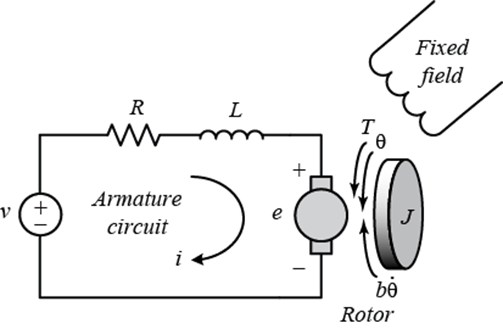

## Physical parameters

For this example, we will assume the following values for the physical parameters. These values were derived by experiment from an actual motor in Carnegie Mellon's undergraduate controls lab [2].

% Physical Parameter Definition

J = 3.2284E-6;      % Rotor inertia (kg.m^2)
B_0 = 3.5077E-6;    % coefficient of viscous friction at the joint (Nms)
Kb = 0.0274;        % electromotive force constant (V/rad/sec)
Kt = 0.0274;        % motor torque constant (Nm/Amp)
R = 4;              % armature resistance (ohm)
L = 2.75E-6;        % armature inductance (H)

## System Model

In this example, a single-link direct-drive manipulator is actuated by a DC motor as described above. The schematic of the electromechanical system is as following:

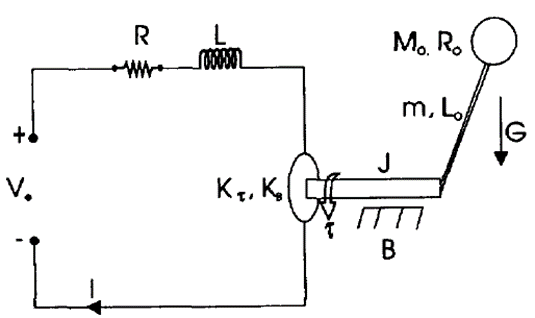

The mechanical dynamics are assumed to be of the form [1]:

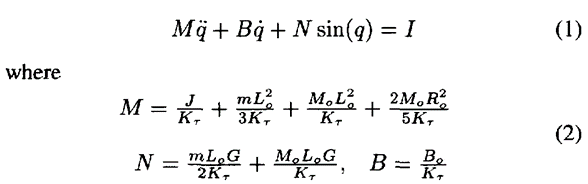

The electrical subsystem dynamics for the permanent magnet brush dc motor are assumed to be: 

For this example, we will assume the following values for the Robotic Load

- Link Length = 10cm;     

- Link Mass = 10gram;

- Load Radius = 2.5cm;

- Load Mass = 10gram;    

L_0 = 0.1;      % Link length (m)
m = 0.01;       % mass (kg) of the link
G = 9.8;        % Gravity Coeficient (m/s^2)
M_0 = 0.01;     % Load Mass (kg)
R_0 = 0.025;    % Radius of the Load (m)

M = (J/Kt) + ((m*L_0^2)/(3*Kt)) + ((M_0*L_0^2)/Kt) + ((2*M_0*R_0^2)/(5*Kt))

M = 0.0051

N = ((m*L_0*G) / (2*Kt)) + ((M_0*L_0*G)/Kt)

N = 0.5365

B = B_0/Kt

B = 1.2802e-04

### Transfer Function

Applying the Laplace transform, the above modeling equations can be expressed in terms of the Laplace variable *s*.


$$G(s) = \frac{1}{LMs^3 + s^2LB + s^2RM + sLN + sK_B + sRB + RN)$$


s = tf('s');
G = 1 / (s^3*L*M + s^2*L*B + s^2*R*M + s*L*N +s*Kb + s*R*B + R*N)

G =
 
                        1
  ----------------------------------------------
  1.396e-08 s^3 + 0.0203 s^2 + 0.02791 s + 2.146
 
Continuous-time transfer function.
Model Properties


disp(['Open Loop Stability: ', num2str(isstable(G))])

Open Loop Stability: 1


damp(G)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -6.87e-01 + 1.03e+01i     6.69e-02       1.03e+01         1.45e+00    
 -6.87e-01 - 1.03e+01i     6.69e-02       1.03e+01         1.45e+00    
 -1.45e+06                 1.00e+00       1.45e+06         6.88e-07    


### Step Responses

The uncompensated open-loop system performance is: 

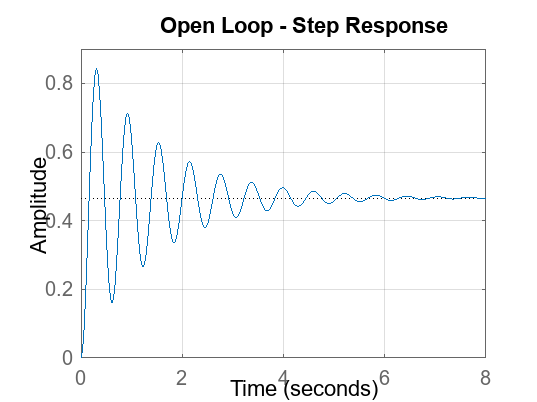

step(G)
title('Open Loop - Step Response')
grid on;

### Analysis

From the plot we see that when 1 Volt is applied to the system the robotic load position could only achieve maximum of around 0.5rad at settling. There is a huge overshoot of of 81%, which settled after 5.5sec. 

stepinfo(G)

ans = struct with fields:
         RiseTime: 0.1068
    TransientTime: 5.5596
     SettlingTime: 5.5596
      SettlingMin: 0.1602
      SettlingMax: 0.8435
        Overshoot: 81.0135
       Undershoot: 0
             Peak: 0.8435
         PeakTime: 0.3056


damp(G)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -6.87e-01 + 1.03e+01i     6.69e-02       1.03e+01         1.45e+00    
 -6.87e-01 - 1.03e+01i     6.69e-02       1.03e+01         1.45e+00    
 -1.45e+06                 1.00e+00       1.45e+06         6.88e-07    


Since the one real pole is so much faster than the complex conjugate poles (its real part is much more negative) its effect on the dynamic response of the system will be mimimal. Therefore, the damping ( = 0.0643) and the natural frequency ( = 10.3) of the complex conjugate poles will primarily indicate the response of the open-loop system.

With a 1-radian step reference, the design criteria can be assumed as following.

- peak time less than 1 sec

- Overshoot less than 4%

Now let's design a controller using the **root locus** method.

## Root Locus

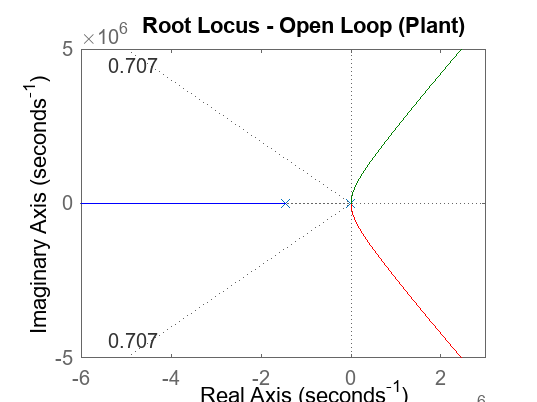

zeta = 0.707;
wn = 0;
rlocus(G)
title('Root Locus - Open Loop (Plant)')
sgrid(zeta, wn)

Solving following equation for the overshoot less than 4% will yield a damping ratio of 0.707.


$$\zeta =\sqrt{\frac{\ln \left(\zeta^2 \right)}{\pi^2 -\ln \left(\zeta^2 \right)}}$$


In addition to overshoot, for short settling time. So placing a pole having shorter real part will be suitable for our system.


$$t_s = \frac{4}{\sigma}$$


To achieve the desired criteria the root locus should pass with in the rays of $\zeta$ and smaller $\sigma$. Right now this is not the case. 

### PD Controller

The PD controller adds a zero to the open loop system, which will have the following form:


$$C(s) = K(s+z)$$



$$C(s) = Ks + Kz = k_d s + k_p$$


Following three scenarios can be analyzed to see which will let the root locus to pass through the desired region as discussed above.

- placing the zero right of the poles

- placing the zero between the poles

- placing the zero left of the poles

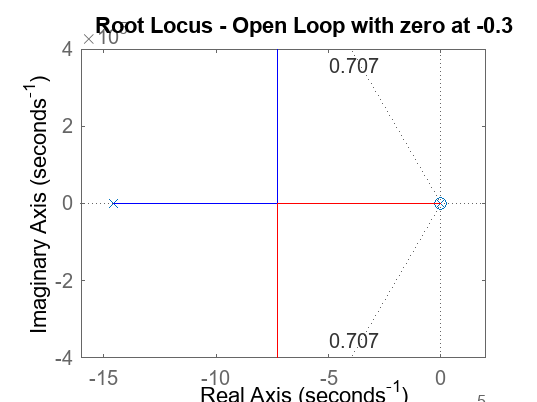

% placing the zero right of the poles
rlocus(G*(s + 0.3))
title('Root Locus - Open Loop with zero at -0.3')
sgrid(zeta, wn)

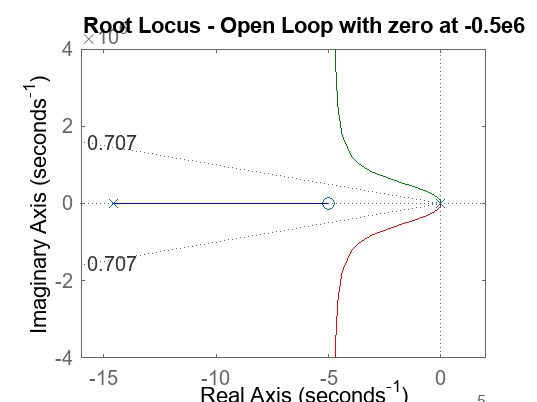


% placing the zero between the poles
rlocus(G*(s + 0.5E6))
title('Root Locus - Open Loop with zero at -0.5e6')
sgrid(zeta, wn)

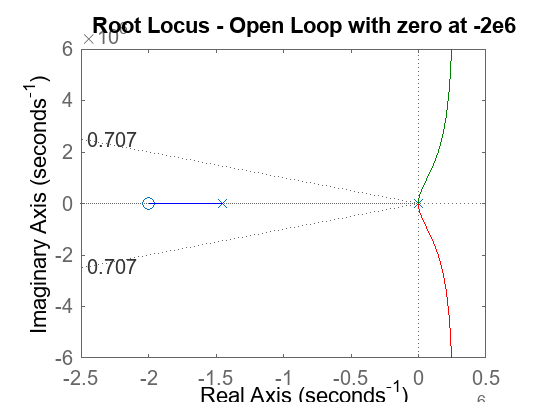


%placing the zero left of the poles
rlocus(G*(s + 2E6))
title('Root Locus - Open Loop with zero at -2e6')
sgrid(zeta, wn)

The first scenario gives us our root locus in the desired region between the $\zeta$.

### Finding the $k_p$ gain

The root locus is already within the rays of $\zeta$ that we selected now lets find a gain of the pole with shorter real part i.e. $\sigma$.

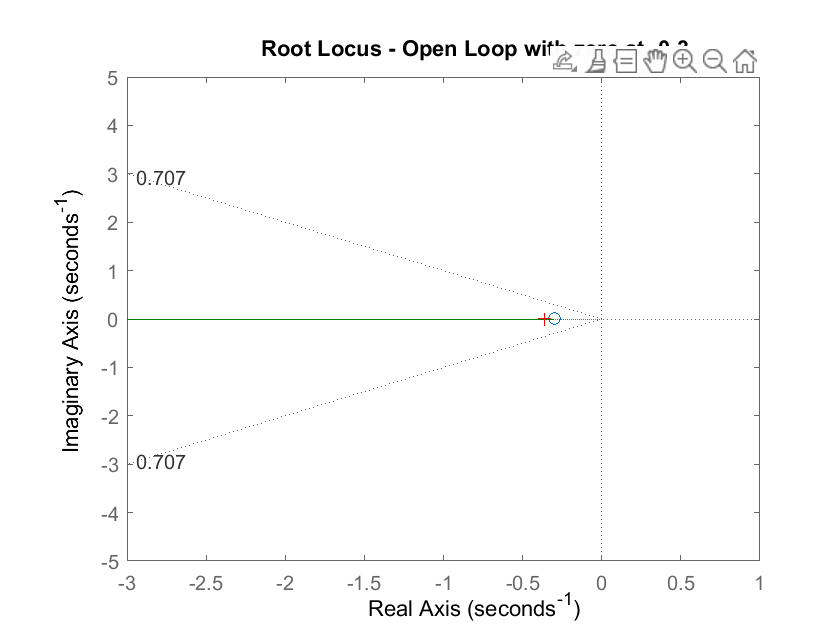

Select a point in the graphics window


selected_point = -0.3618 - 0.0103i

kp = 34.1471

poles = 1.0e+06 *

   -1.4529
   -0.0017
   -0.0000


% placing the zero right of the poles
rlocus(G*(s + 0.3))
axis([-3 1 -5 5])
title('Root Locus - Open Loop with zero at -0.3')
sgrid(zeta, wn)
[kp, poles] = rlocfind(G * (s + 0.3))

## System Response with PD Controller

The compensated system performance is: 

% PD Controller Gains
kp = kp;
kd = kp*0.3;
ki = 0;
C = pid(kp, ki, kd)

C =
 
             
  Kp + Kd * s
             

  with Kp = 34.1, Kd = 10.2
 
Continuous-time PD controller in parallel form.
Model Properties


t = 0:0.01:1;
G_cl = feedback(C*G, 1)

G_cl =
 
                10.24 s + 34.15
  --------------------------------------------
  1.396e-08 s^3 + 0.0203 s^2 + 10.27 s + 36.29
 
Continuous-time transfer function.
Model Properties


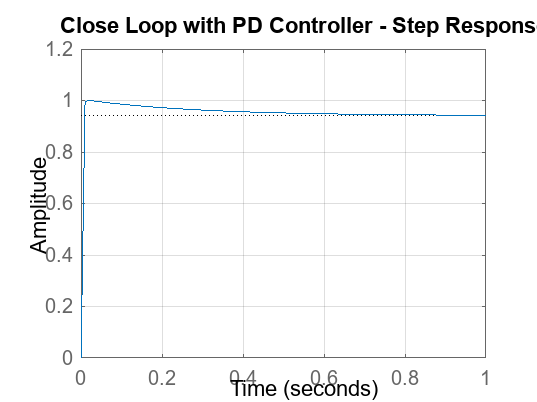

step(G_cl,t);
grid on;
title('Close Loop with PD Controller - Step Response');

### System performance

System analysis with PD Controller

stepinfo(G_cl)

ans = struct with fields:
         RiseTime: 0.0035
    TransientTime: NaN
     SettlingTime: NaN
      SettlingMin: 0.8518
      SettlingMax: 1.0010
        Overshoot: 6.3857
       Undershoot: 0
             Peak: 1.0010
         PeakTime: 0.0155


damp(G_cl)

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
 -3.56e+00     1.00e+00       3.56e+00         2.81e-01    
 -5.03e+02     1.00e+00       5.03e+02         1.99e-03    
 -1.45e+06     1.00e+00       1.45e+06         6.88e-07    


## References

- D. M. Dawson, Carroll, and M. Schneider, “Integrator Backstepping Control of a Brush DC Motor Turning a Robotic Load,” IEEE Trans. Contr. Sys. Tech., vol. 2, no. 3, pp. 233-244, Sept. 1994.

- [Control Tutorials for MATLAB & Simulink](https://ctms.engin.umich.edu/CTMS/index.php?example=MotorPosition&section=SystemModeling)